# German Stocks - Monte Carlo

## 1.

Run the script `stocksDE8.mlx`. This creates the variables

- `scores`: Scores resulting from a principal component analysis (PCA) of the stock returns

- `stockIdx`: Index of the one stock of interest

stocks =     0.0014   -0.0209   -0.0193    0.0163   -0.0127   -0.0012    0.0207   -0.0143   -0.0106   -0.0103   -0.0135   -0.0113   -0.0103   -0.0022   -0.0130   -0.0049   -0.0119    0.0118    0.0018   -0.0333   -0.0124    0.0039    0.0059    0.0063   -0.0121    0.0087   -0.0116   -0.0102   -0.0186   -0.0165
    0.0008    0.0206    0.0107    0.0267    0.0075    0.0128    0.0143    0.0157    0.0177    0.0612    0.0081   -0.0052    0.0126    0.0321    0.0166    0.0043    0.0075    0.0213    0.0217    0.0177    0.0166    0.0215   -0.0091    0.0153    0.0106    0.0179    0.0195    0.0102    0.0311    0.0057
    0.0106    0.0046    0.0106    0.0291    0.0092    0.0045    0.0114   -0.0051    0.0138   -0.0097    0.0091    0.0057    0.0024    0.0093    0.0100    0.0030    0.0044    0.0133   -0.0018    0.0339    0.0133    0.0112    0.0176    0.0081    0.0018    0.0033   -0.0805    0.0083    0.0209    0.0020
    0.0080    0.0030    0.0044   -0.0044    0.0133    0.0080   -0.0007    0.0051    0.00

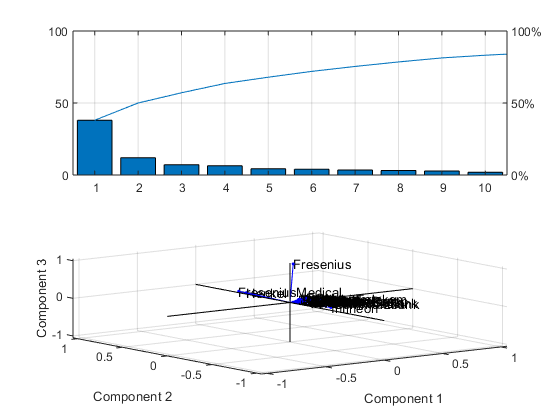

PCAfit =    -0.0307
    0.0207
    0.0362
    0.0139
   -0.0010
   -0.0192
   -0.0080
    0.0158
    0.0036
   -0.0026


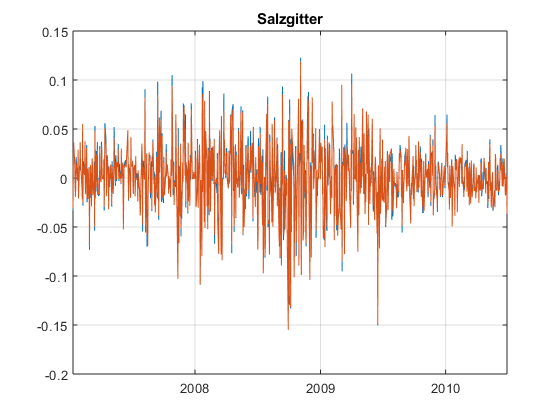

stocksDE8;

## 2.

Calculate the vector of mean values and the covariance matrix for the scores of the first 10 principal components.

muScores = mean(scores(:,1:10))

muScores = 	1.0e+-17 *

   -0.3025    0.1513    0.0618    0.2138   -0.0117   -0.0506   -0.0374   -0.0541    0.0557   -0.0828


sigScores = cov(scores(:,1:10))

sigScores =     0.0095   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0030   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0018   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0016    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000    0.0011    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0010   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0009   -0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0008   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0007   -0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.000


% Alternative: gaussian mixture (you could also use a copula)
% distScores = gmdistribution.fit(scores(:,1:10),10, ...
%      'SharedCov',true);

## 3.

Generate 2 million random vectors from a multivariate normal distribution with the parameters estimated in step 2.

rndScores = mvnrnd(muScores, sigScores, 2000000)

rndScores =    -0.0643   -0.0316   -0.0536   -0.0574   -0.0099   -0.0305    0.0089    0.0057    0.0368   -0.0280
   -0.0758    0.0488    0.0369   -0.0351   -0.0178   -0.0408   -0.0417    0.0494    0.0516    0.0097
   -0.0127   -0.0769   -0.0660   -0.0190   -0.0047    0.0445   -0.0526    0.0065   -0.0557   -0.0062
   -0.0099    0.0214   -0.0498   -0.0215   -0.0116   -0.0022   -0.0396    0.0434   -0.0140    0.0109
    0.1254   -0.0843    0.0881    0.0599    0.0373   -0.0366   -0.0112    0.0230   -0.0170    0.0347
   -0.0075   -0.0268    0.0014   -0.0353    0.0303    0.0091    0.0284   -0.0112    0.0386   -0.0207
    0.0576    0.0600    0.0202    0.0113   -0.0210   -0.0313   -0.0571   -0.0614    0.0150    0.0470
   -0.0499   -0.0768   -0.0078    0.0176    0.0127   -0.0389    0.0140   -0.0017    0.0307   -0.0391
    0.0456   -0.0548    0.0005    0.0003    0.0082    0.0317   -0.0152    0.0378    0.0345   -0.0008
    0.1942    0.1171   -0.0368    0.0090    0.0051    0.0175    0.0034    0.007


% Alternative: gaussian mixture (you could also use a copula)
% rndScores = random(distScores,2000000);

## 4.

Convert the random scores from step 3 to a 20-by-100000 matrix of random stock returns of the stock of interest. **Hint** Multiply the random scores with the corresponding PCA coefficients.

rndReturns = reshape(rndScores*coeff(stockIdx,1:10)', 20, [])

rndReturns =     0.0208   -0.0664   -0.0855    0.0369   -0.0036   -0.0188    0.0046    0.0146   -0.0138    0.0245   -0.0008    0.0031   -0.0062    0.0369   -0.0018    0.0149    0.0320    0.0547    0.0256   -0.0174   -0.0185    0.0273   -0.0045   -0.0862    0.0087    0.0573    0.0153   -0.0192    0.0694    0.0293   -0.0230    0.0550    0.0123   -0.0059   -0.0025   -0.0133   -0.0069    0.0015    0.0182    0.0389    0.0272    0.0346    0.0292   -0.0233    0.0450    0.0296   -0.0614    0.0176   -0.0369    0.0451
    0.0158   -0.0504    0.0022    0.0213   -0.0457    0.0069   -0.0027    0.0071   -0.0203   -0.0217    0.0053    0.0177    0.0003   -0.0388   -0.0135   -0.0078    0.0316    0.0215   -0.0120   -0.0210   -0.0746   -0.0042   -0.0345    0.0357   -0.0642    0.0190    0.0339    0.0172   -0.0025   -0.0309    0.0394   -0.0886   -0.0047   -0.0320    0.0531    0.0614    0.0050    0.0022    0.0026    0.0312   -0.0470    0.0513    0.0056   -0.0278   -0.0260    0.0685    0.0117   -0.0475    0.

## 5.

Convert the returns into prices using the following formula:

`prices = ``exp``(``cumsum``(returns));`

simPrices = exp(cumsum(rndReturns))

simPrices =     1.0210    0.9358    0.9180    1.0376    0.9964    0.9814    1.0046    1.0147    0.9863    1.0249    0.9992    1.0031    0.9938    1.0375    0.9982    1.0150    1.0325    1.0562    1.0259    0.9828    0.9816    1.0277    0.9955    0.9174    1.0087    1.0590    1.0154    0.9810    1.0719    1.0297    0.9773    1.0566    1.0124    0.9941    0.9975    0.9868    0.9931    1.0015    1.0184    1.0397    1.0275    1.0352    1.0297    0.9770    1.0460    1.0300    0.9405    1.0177    0.9638    1.0461
    1.0373    0.8898    0.9200    1.0599    0.9519    0.9881    1.0019    1.0220    0.9665    1.0028    1.0046    1.0210    0.9941    0.9981    0.9848    1.0072    1.0657    1.0792    1.0137    0.9624    0.9111    1.0233    0.9617    0.9508    0.9460    1.0793    1.0504    0.9980    1.0691    0.9984    1.0165    0.9670    1.0076    0.9628    1.0519    1.0493    0.9980    1.0037    1.0210    1.0726    0.9804    1.0896    1.0355    0.9501    1.0192    1.1030    0.9516    0.9705    0.9

## 6. 

Estimate the 1% Value at Risk of the final stock price.

finalPrices = simPrices(end,:)

finalPrices =     1.1358    0.9613    0.7919    1.0405    1.1004    1.0037    1.1154    1.1886    1.0349    0.9991    1.2189    1.0096    0.7820    0.9719    1.1061    0.9426    1.5830    0.7998    1.0064    0.9657    0.6739    0.9992    0.8283    0.9182    0.7786    0.9417    0.9971    1.1235    0.9970    0.9426    1.1419    0.8434    0.9720    0.8907    1.2066    1.0855    0.8906    0.8423    1.0266    1.2838    0.8156    1.0823    1.0052    0.9313    1.1065    1.0270    0.9575    0.7754    0.9050    0.9339


VaR = prctile(finalPrices,1)

VaR = 0.7065

## BONUS

Visualize final price distribution

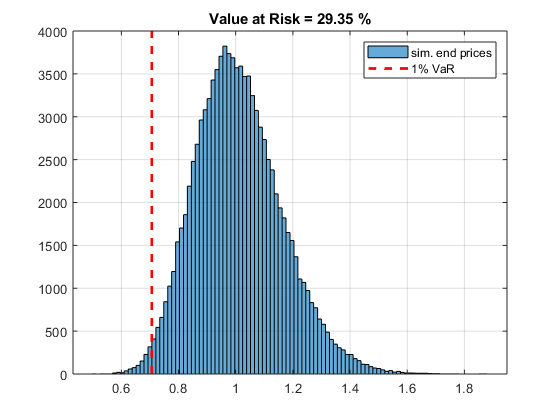

histogram(finalPrices,100)
grid('on')
hold('on')
plot(VaR*ones(2,1),ylim,'r--','LineWidth',2)
hold('off')
title(['Value at Risk = ', num2str(100*(1-VaR),'%.2f %%')])
legend('sim. end prices','1% VaR')